# Examen Parcial Señales Aleatorias y Ruido

Lorena Patricia Barrera Rodríguez

**164694**

## Ejercicio 1. Proceso Poisson.

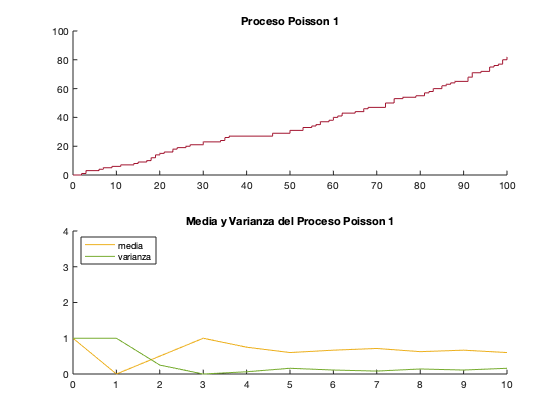

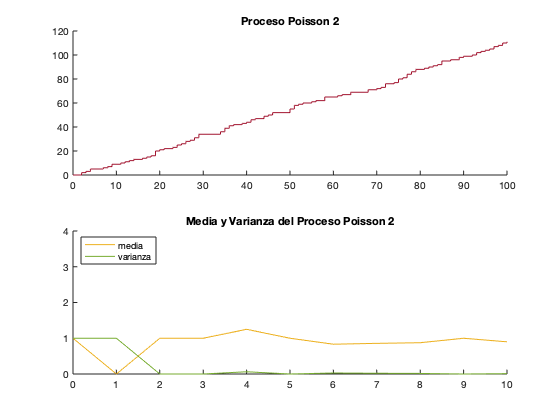

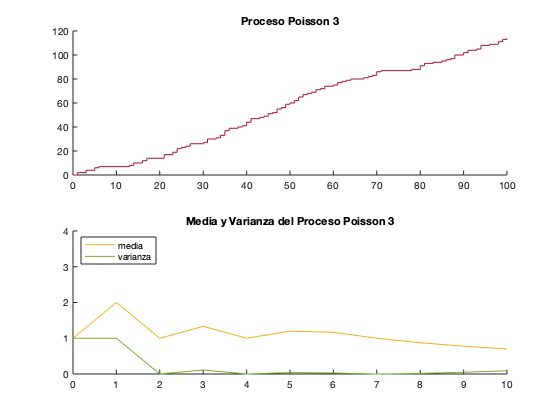

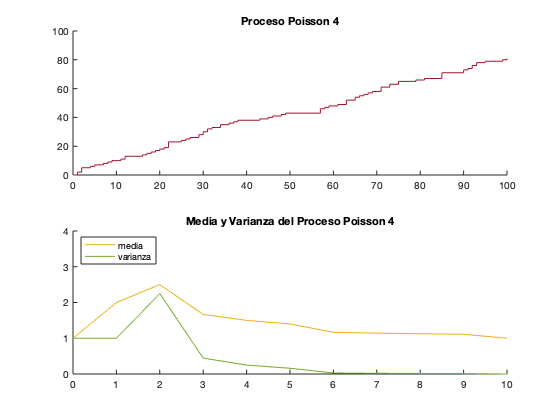

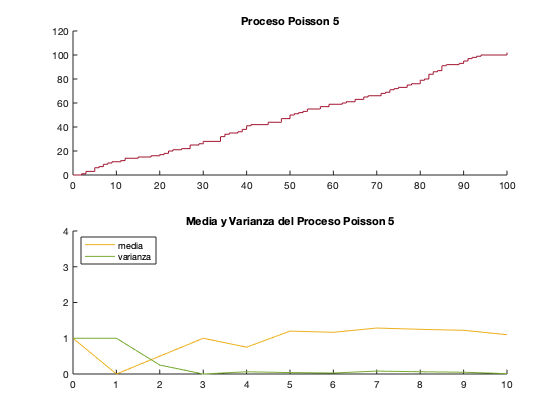

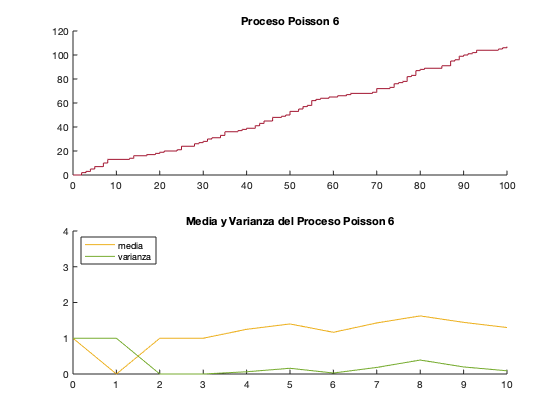

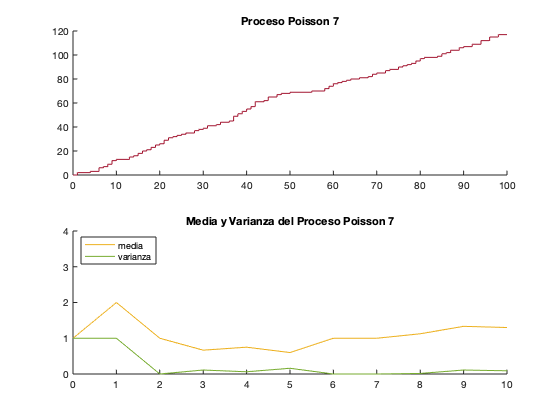

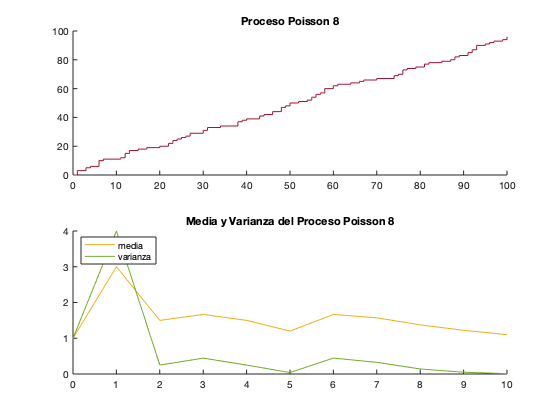

realizaciones = 10;
eventos = 100;
lambda = 1;

T = 0 : eventos;
X = zeros(realizaciones, eventos+1);

% Realizaciones y sus gráficas
for i = 1:realizaciones
    N(1) = 0;
    % Media muestral --> E = Sumatoria(xi)/n
    E(1) = lambda;  
    % Varianza muestral --> V = E ((X - lambda) ^ 2)
    V(1) = lambda; 
    
    for  t = 1:eventos
        % N(t) son eventos ocurridos hasta t. 
        % Entonces le sumamos los nuevos eventos.
        N(t+1) = N(t) + poissrnd(lambda);
        
        % Media muestral
        E(t+1) = N(t+1) / t;
        
        % Varianza muestra
        V(t+1) = (E(t+1) - lambda)*(E(t+1) - lambda);
    end
    
    figure
        % Gráfica de las realizaciones
        subplot(2,1,1)
            stairs (T, N, 'color', [0.6350, 0.0780, 0.1840]);
            title("Proceso Poisson " + i);
            box off;
            
        % Gráfica de la media y la varianza 
        subplot(2,1,2)
            hold on;
            % Media: amarillo
            plot (T, E, 'color', [0.9290, 0.6940, 0.1250]);
            % Varianza: verde
            plot (T, V, 'color', [0.4660, 0.6740, 0.1880]);
            axis([0, realizaciones, 0, 4]);
            legend({'media','varianza'},'Location','northwest');
            title("Media y Varianza del Proceso Poisson " + i);
            box off;
            hold off;
    % Guarda cada realización en una matriz 
    X(i, :) = N;
end

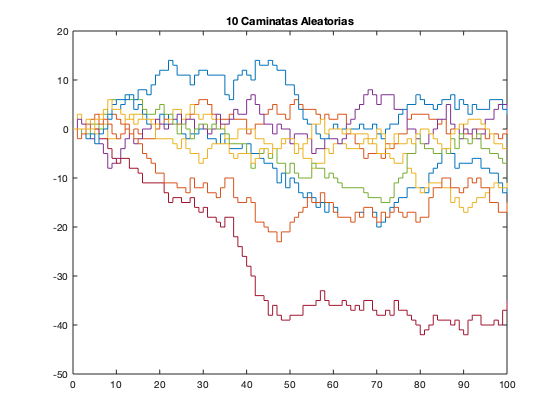


% Caminata aleatoria
figure
for i = 1:realizaciones
    % Se eligen realizaciones aleatorias
    id1 = randi(realizaciones);
    id2 = randi(realizaciones);
    
    % Evita que haya realizaciones iguales para que no de cero
    while (id2 == id1)
        id2 = randi(realizaciones);
    end
    
    % Se asignan las realizaciones. La izquierda suma y la derecha resta.
    Izquierda = X(id1, :);
    Derecha = -X(id2, :);
    
    %Gráfica de la caminata aleatoria.
    stairs(T, Izquierda+Derecha);
    title("10 Caminatas Aleatorias");
    hold on;
end

## Ejercicio 2. Ondas telegráficas.

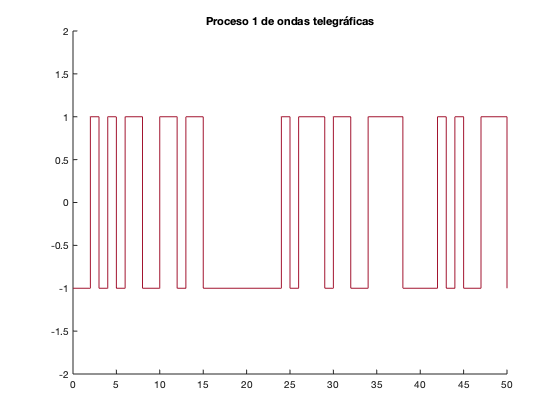

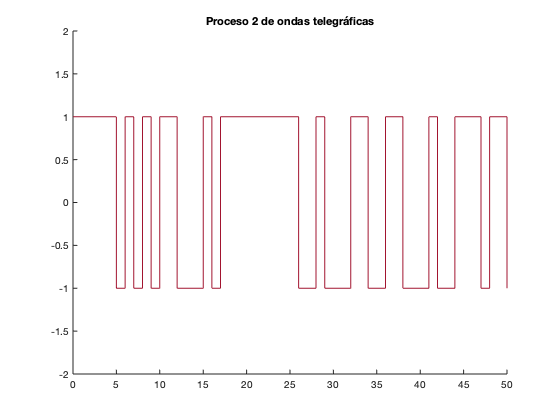

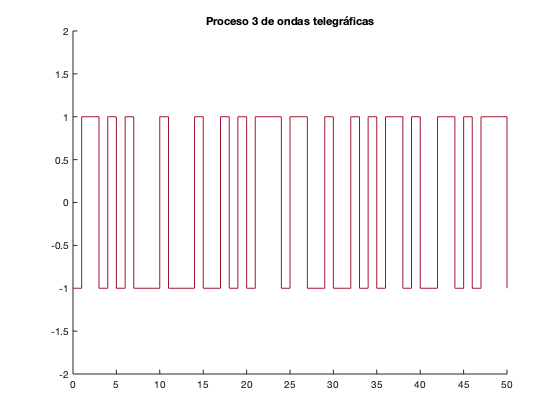

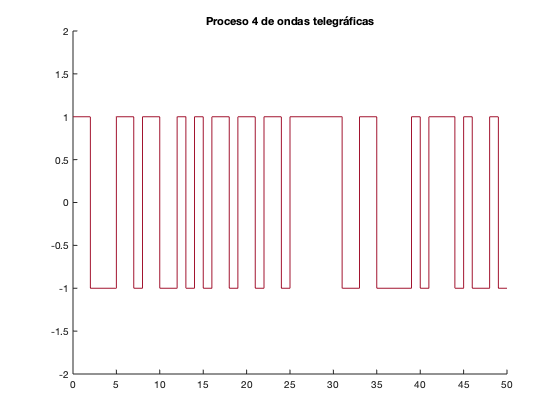

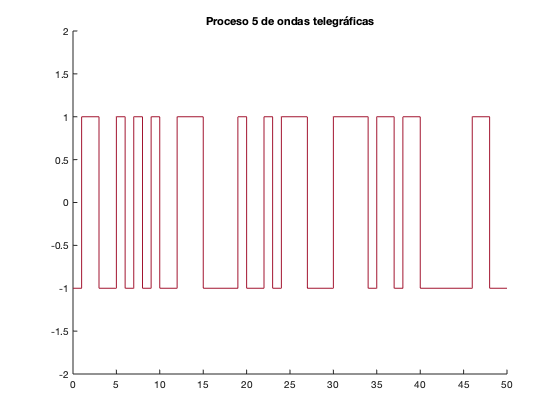

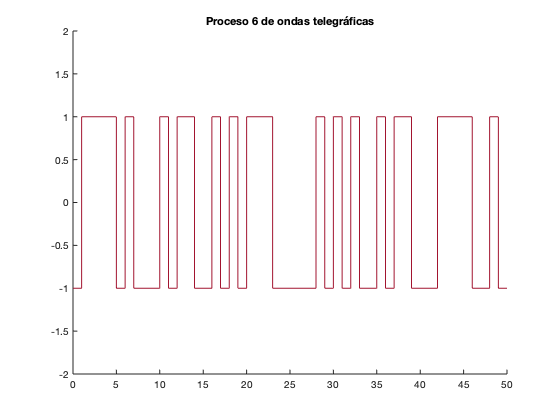

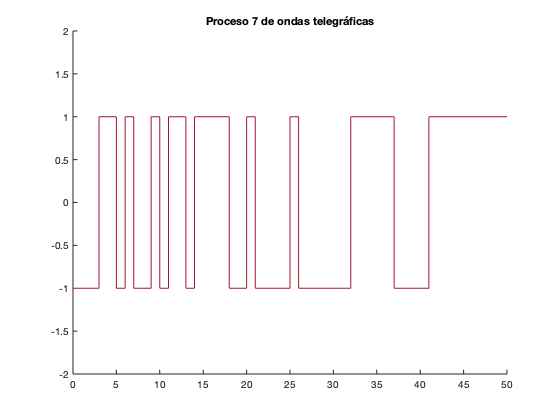

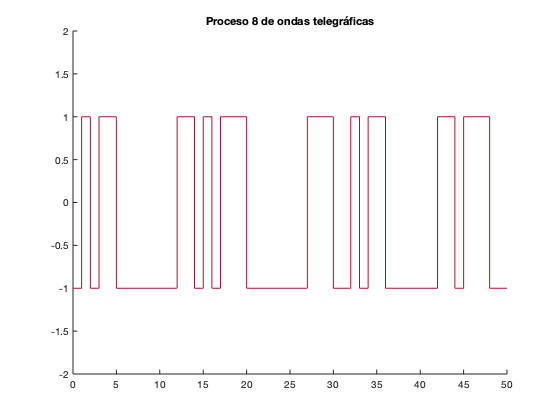

%Ondas telegráficas
realizaciones = 10;
minutos = 50;
lambda = 0.4;

T = 0 : minutos;

% Realizaciones y sus gráficas
for i = 1: realizaciones
    
    % Inicia en -1 o 1
    W(1) = 2 * binornd(1, 0.5) - 1;
    
    Es(1) = lambda;
    
    CxD = zeros(realizaciones, minutos + 1);
    
    for  t = 1: minutos
        % Crea una Bernoulli y la modifica para que de -1 o 1
        Z = 2 * binornd(1, 0.5) - 1;
        
        W(t+1) = Z;
        
    end
    
    figure
        % Gráfica de las realizaciones
        stairs (T, W, 'color', [0.6350, 0.0780, 0.1840]);
        axis([0, minutos, -2, 2])
        title("Proceso " + i + " de ondas telegráficas");
        box off;
        
end



% Probabilidades de que sea 0 o 1 en el tiempo 20 y 30
t1 = 20;
t2 = 30;

ProbaT1 = (1/2) * (1 - exp(-2 * lambda * t1))

ProbaT1 = 0.5000

ProbaT2 = (1/2) * (1 - exp(-2 * lambda * t2))

ProbaT2 = 0.5000

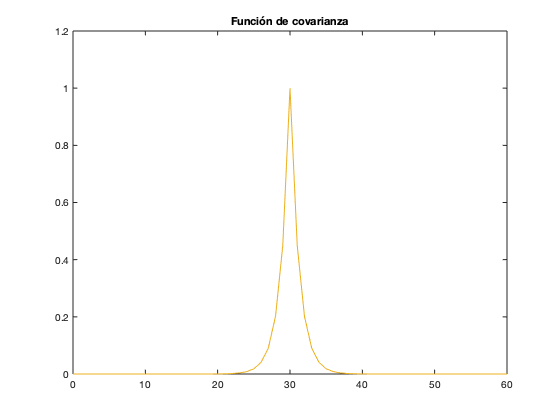



% Función de covarianza
tiempo = 30;
minutos = 2*tiempo;
T = 0 : minutos;

Cx = zeros(1, minutos + 1);

for i = 1:(minutos + 1)
    t = T(i);
    Cx(i) = exp(-2 * lambda * abs(tiempo - t));
end

plot(T, Cx, 'color', [0.9290, 0.6940, 0.1250])
title("Función de covarianza")
axis ([0,minutos,0, 1.2])